# Behavioural analysis

Behavioural analysis, to reproduce Fig. 2.

% The behavioural analysis uses a dictionary object, where the data of each
% subject is stored as a key:value pair. This dictionary is extracted from
% multiple data files, using the function loadData(). To save in space, we
% load this dictionary directly here.

% data_struct = loadData();
load('../data/behaviour.mat')
subjects = {};
keys = data_struct.keys;
for i = 1:length(keys)
    subj = data_struct(keys{i});
    if subj.include
        subjects{end+1} = keys{i};
    end
end
N = length(subjects);

% This is color brewer's set 1 (used only for visualization):

cb = [0.8941    0.1020    0.1098
    0.2157    0.4941    0.7216
    0.3020    0.6863    0.2902
    0.5961    0.3059    0.6392
    0.8588    0.3569    0.3216
    1.0000    0.4980         0
    1.0000    1.0000    0.2000
    0.6510    0.3373    0.1569
    0.9686    0.5059    0.7490
    0.6000    0.6000    0.6000];

## 1. Accuracy

Contrasting mean accuracy and d' for the three tasks.

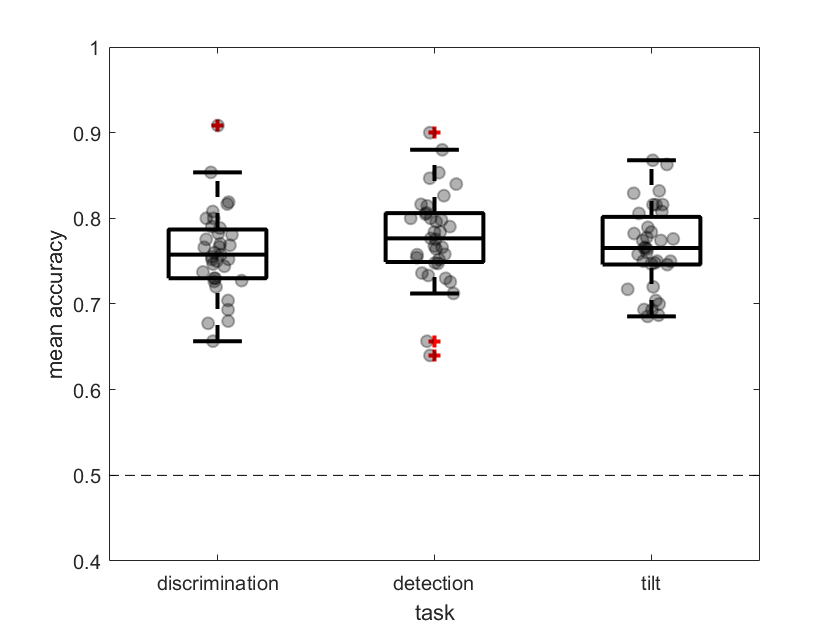

meanAccDet = []; %detection
meanAccDis = []; %discrimination
meanAccTilt  = []; %tilt recognition

mean_dprimeDet = [];
mean_dprimeDis = [];
mean_dprimeTilt = [];

responseBiasDet = [];
responseBiasDis = [];
responseBiasTilt = [];

for s = 1:length(subjects)
    
    subject = data_struct(subjects{s});
    
    %trial exclusion is achieved by logical indexing. The conditions for
    %trial exclusion are spelled out in loadData.m
    
    AccDet = subject.DetCorrect(find(subject.DetInclude));
    AccDis = subject.DisCorrect(find(subject.DisInclude));
    AccTilt = subject.TiltCorrect(find(subject.TiltInclude));
    
    dprimeDet = norminv(nanmean(subject.DetResp(subject.DetSignal == 1 & subject.DetInclude))) - ...
        norminv(nanmean(subject.DetResp(subject.DetSignal == 0 & subject.DetInclude)));

    dprimeDis = norminv(nanmean(subject.DisResp(subject.DisSignal == 1 & subject.DisInclude))) - ...
        norminv(nanmean(subject.DisResp(subject.DisSignal == 0 & subject.DisInclude)));
    
    dprimeTilt = norminv(nanmean(subject.TiltResp(subject.TiltSignal == 1 & subject.TiltInclude))) - ...
        norminv(nanmean(subject.TiltResp(subject.TiltSignal == 0 & subject.TiltInclude)));
    
    responseBiasDet(s) = nanmean(subject.DetResp(find(subject.DetInclude)));
    responseBiasDis(s) = nanmean(subject.DisResp(find(subject.DisInclude)));
    responseBiasTilt(s) = nanmean(subject.TiltResp(find(subject.TiltInclude)));

  
    meanAccDet(end+1) = nanmean(AccDet);
    meanAccDis(end+1) = nanmean(AccDis);
    meanAccTilt(end+1) = nanmean(AccTilt);
    
    mean_dprimeDet(s) = dprimeDet;
    mean_dprimeDis(s) = dprimeDis;
    mean_dprimeTilt = dprimeTilt;

    
end

% plot figure 2A
noise1 = normrnd(0,0.05,1,N);
noise2 = normrnd(0,0.05,1,N);
noise3 = normrnd(0,0.05,1,N);

figure; hold on;
h=boxplot([meanAccDis;meanAccDet; meanAccTilt]','Colors','k');
set(h,{'linew'},{2})
scatter(ones(N,1)+noise1',meanAccDis,[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1, 'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(2*ones(N,1)+noise2',meanAccDet,[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(3*ones(N,1)+noise2',meanAccTilt,[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
ylabel('mean accuracy');

xlim([0.5,3.5]); xlabel('task');
ylim([0.4,1]);
plot([0.5,3.5],[0.5,0.5],'k--')
set(gca,'xtick',[1:3],'xticklabel',{'discrimination','detection','tilt'})
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png';
s.Width = 12;
s.Height = 10;
hgexport(fig,'figures/accuracy',s);



% accuracy_table = table([ones(35,1); 2*ones(35,1); 3*ones(35,1)], ...
%     repmat((1:35)',3,1),...
%     [meanAccDet'; meanAccDis'; meanAccTilt'], ...
%     'VariableNames',{'task','subj','acc'});
% writetable(accuracy_table,'accuracy_table.csv')



## 2. Confidence ratings

%mean confidence ratings

conf_C = []; %clockwise (discrimination)
conf_A = []; %anticlockwise (discrimination)
conf_Y = []; %yes (detection)
conf_N = []; %no (detection)
conf_V = []; %vertical (tilt recognition)
conf_T = []; %tilted (tilt recognition)

% confidence histograms
hist_C = [];
hist_A = [];
hist_Y = [];
hist_N = [];
hist_V = [];
hist_T = [];



for s = 1:length(subjects)
    
    subject = data_struct(subjects{s});
    
        conf_C(s) = nanmean(subject.DisConf(subject.DisResp==1 & subject.DisInclude==1));
        conf_A(s) = nanmean(subject.DisConf(subject.DisResp==0 & subject.DisInclude==1));
        conf_Y(s) = nanmean(subject.DetConf(subject.DetResp==1 & subject.DetInclude==1));
        conf_N(s) = nanmean(subject.DetConf(subject.DetResp==0 & subject.DetInclude==1));
        conf_T(s) = nanmean(subject.TiltConf(subject.TiltResp==1 & subject.TiltInclude==1));
        conf_V(s) = nanmean(subject.TiltConf(subject.TiltResp==0 & subject.TiltInclude==1));
        
        hist_C(s,:) = hist(subject.DisConf(subject.DisResp==1 & subject.DisInclude==1),1:6);
        hist_A(s,:) = hist(subject.DisConf(subject.DisResp==0 & subject.DisInclude==1),1:6);
        hist_Y(s,:) = hist(subject.DetConf(subject.DetResp==1 & subject.DetInclude==1),1:6);
        hist_N(s,:) = hist(subject.DetConf(subject.DetResp==0 & subject.DetInclude==1),1:6);
        hist_T(s,:) = hist(subject.TiltConf(subject.TiltResp==1 & subject.TiltInclude==1),1:6);
        hist_V(s,:) = hist(subject.TiltConf(subject.TiltResp==0 & subject.TiltInclude==1),1:6);
  
end


## 3. Individual response-conditional type-2 ROC curves

% To run this analysis, we need confidence coutns for each stimulus x
% response combination. We start with Discrimination.
% AC stands for trials where the stimulus was A(nticlockwise), and the
% response was C(lockwise). 

[ACGroup, CCGroup,CAGroup, AAGroup] = deal([]);

%In detection the format is more self explanatory. Signal is target
%presence, Noise is target absence.
[SignalYesGroup, SignalNoGroup, NoiseYesGroup, NoiseNoGroup] = deal([]);

% In tilt recognition, TV stands for trials where the stimulus was
% T(ilted), and the response was V(ertical).
[TTGroup, TVGroup, VTGroup, VVGroup] = deal([]);

%Finally, nR vectors represent responsexconfidence vectors for each
%stimulus, in the format used by meta-d' packages. S1 is A and S2 is C.
[nR_S1,nR_S2,nR_signal_nR_noise, nR_tilted, nR_vertical] = deal([]);


for s=1:length(subjects)
    
    subject = data_struct([subjects{s}]);
    

        %break into taskXresponseXsignal
        DisCC = reshape(histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==1 & subject.DisInclude==1),1:6),6,1);
        DisCA = reshape(histc(subject.DisConf(subject.DisSignal==1 & subject.DisResp==0 & subject.DisInclude==1),1:6),6,1);
        DisAC = reshape(histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==1 & subject.DisInclude==1),1:6),6,1);
        DisAA = reshape(histc(subject.DisConf(subject.DisSignal==0 & subject.DisResp==0 & subject.DisInclude==1),1:6),6,1);
        
        DetSignalYes = reshape(histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==1 & subject.DetInclude==1),1:6),6,1);
        DetSignalNo = reshape(histc(subject.DetConf(subject.DetSignal==1 & subject.DetResp==0 & subject.DetInclude==1),1:6),6,1);
        DetNoiseYes = reshape(histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==1 & subject.DetInclude==1),1:6),6,1);
        DetNoiseNo = reshape(histc(subject.DetConf(subject.DetSignal==0 & subject.DetResp==0 & subject.DetInclude==1),1:6),6,1);
        
        TiltTT = reshape(histc(subject.TiltConf(subject.TiltSignal==1 & subject.TiltResp==1 & subject.TiltInclude==1),1:6),6,1);
        TiltTV = reshape(histc(subject.TiltConf(subject.TiltSignal==1 & subject.TiltResp==0 & subject.TiltInclude==1),1:6),6,1);
        TiltVT = reshape(histc(subject.TiltConf(subject.TiltSignal==0 & subject.TiltResp==1 & subject.TiltInclude==1),1:6),6,1);
        TiltVV = reshape(histc(subject.TiltConf(subject.TiltSignal==0 & subject.TiltResp==0 & subject.TiltInclude==1),1:6),6,1);
        
        nR_S1(s,:) = [reshape(DisAA(end:-1:1),1,[]) reshape(DisAC,1,[])];
        nR_S2(s,:) = [reshape(DisCA(end:-1:1),1,[]) reshape(DisCC,1,[])];
        nR_signal(s,:) = [reshape(DetSignalNo(end:-1:1),1,[]) reshape(DetSignalYes,1,[])];
        nR_noise(s,:) = [reshape(DetNoiseNo(end:-1:1),1,[]) reshape(DetNoiseYes,1,[])];
        nR_tilted(s,:) = [reshape(TiltTV(end:-1:1),1,[]) reshape(TiltTT,1,[])];
        nR_vertical(s,:) = [reshape(TiltVV(end:-1:1),1,[]) reshape(TiltVT,1,[])];
        
        
%% UNCOMMENT to plot individual ROCs
%         figure;
%         subplot(1,3,1);
%         hold on;
%         axis equal
        
        %up responses
%         plot([0; cumsum(DisAC(end:-1:1))/sum(DisAC)],...
%             [0; cumsum(DisCC(end:-1:1))/sum(DisCC)], '-*r');

        upAUC(s) = trapz([0; cumsum(DisAC(end:-1:1))/sum(DisAC)],...
            [0; cumsum(DisCC(end:-1:1))/sum(DisCC)]);
        
        ACGroup = [ACGroup [0; cumsum(DisAC(end:-1:1))/sum(DisAC)]];
        CCGroup = [CCGroup [0; cumsum(DisCC(end:-1:1))/sum(DisCC)]];
        
        %down responses
%         plot([0; cumsum(DisCA(end:-1:1))/sum(DisCA)],...
%             [0; cumsum(DisAA(end:-1:1))/sum(DisAA)], '-ok');

        downAUC(s) = trapz([0; cumsum(DisCA(end:-1:1))/sum(DisCA)],...
            [0; cumsum(DisAA(end:-1:1))/sum(DisAA)]);
        
        AAGroup = [AAGroup [0; cumsum(DisAA(end:-1:1))/sum(DisAA)]];
        CAGroup = [CAGroup [0; cumsum(DisCA(end:-1:1))/sum(DisCA)]];
        
%         xlabel('p(conf|false positive)');
%         ylabel('p(conf|hit)');
%         title([subjects{s}, ': discrimination']);
%         set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
%         set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
%         refline(1,0);
%         legend('clockwise', 'anticlockwise', 'Location', 'southeast')
        
        %% plot detection
        if sum(subject.DetSignal==0 & subject.DetResp==1)>1
%             subplot(1,3,2);
%             hold on;
%             axis equal
            
            %yes responses
%             plot([0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)],...
%                 [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)], '-*r');
            
            yesAUC(s) = trapz([0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)],...
                [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)]);
            
            NoiseYesGroup = [NoiseYesGroup [0; cumsum(DetNoiseYes(end:-1:1))/sum(DetNoiseYes)]];
            SignalYesGroup = [SignalYesGroup [0; cumsum(DetSignalYes(end:-1:1))/sum(DetSignalYes)]];
            
            %no responses
%             plot([0; cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)],...
%                 [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)],'-ok');

            noAUC(s) = trapz([0; cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)],...
                [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)]);
            
            NoiseNoGroup = [NoiseNoGroup [0; cumsum(DetNoiseNo(end:-1:1))/sum(DetNoiseNo)]];
            SignalNoGroup = [SignalNoGroup [0;
                cumsum(DetSignalNo(end:-1:1))/sum(DetSignalNo)]];
            
%             xlabel('p(conf|false positive)');
%             ylabel('p(conf|hit)');
%             title('detection');
%             set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
%             set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
%             refline(1,0);
%             legend('signal', 'noise', 'Location', 'southeast')
        end
        
        %% plot tilt recognition
        if sum(subject.TiltSignal==0 & subject.TiltResp==1)>1
%             subplot(1,3,3);
%             hold on;
%             axis equal
            
            %tilted responses
%             plot([0; cumsum(TiltVT(end:-1:1))/sum(TiltVT)],...
%                 [0; cumsum(TiltTT(end:-1:1))/sum(TiltTT)], '-*r');
            
            tiltAUC(s) = trapz([0; cumsum(TiltVT(end:-1:1))/sum(TiltVT)],...
                [0; cumsum(TiltTT(end:-1:1))/sum(TiltTT)]);
            
            VTGroup = [VTGroup [0; cumsum(TiltVT(end:-1:1))/sum(TiltVT)]];
            TTGroup = [TTGroup [0; cumsum(TiltTT(end:-1:1))/sum(TiltTT)]];
            
            %vertical responses
%             plot([0; cumsum(TiltTV(end:-1:1))/sum(TiltTV)],...
%                 [0; cumsum(TiltVV(end:-1:1))/sum(TiltVV)],'-ok');

            verticalAUC(s) = trapz([0; cumsum(TiltTV(end:-1:1))/sum(TiltTV)],...
                [0; cumsum(TiltVV(end:-1:1))/sum(TiltVV)]);
            
            VVGroup = [VVGroup [0; cumsum(TiltVV(end:-1:1))/sum(TiltVV)]];
            TVGroup = [TVGroup [0;
                cumsum(TiltTV(end:-1:1))/sum(TiltTV)]];
            
%             xlabel('p(conf|false positive)');
%             ylabel('p(conf|hit)');
%             title('tilt recognition');
%             set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
%             set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
%             refline(1,0);
%             legend('tilted', 'vertical', 'Location', 'southeast')
        end
end

## 4. Fig. 2 C-D

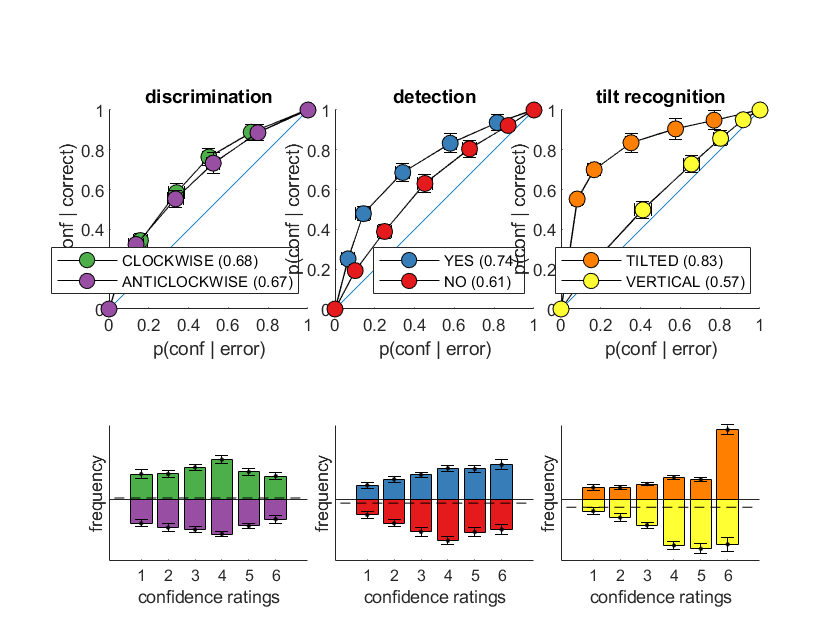

set(0,'defaultAxesFontSize',10)
figure;
ax1=subplot(3,6,[1,2,7,8]);
hold on;
axis equal
refline(1,0);

errorbar(mean(ACGroup,2),mean(CCGroup,2),std(ACGroup')/sqrt(N),std(ACGroup')/sqrt(N),...
    std(CCGroup')/sqrt(N),std(CCGroup')/sqrt(N),'k')
c=plot(mean(ACGroup,2),mean(CCGroup,2), '-ok', 'MarkerFaceColor',cb(3,:),'MarkerSize',8);
errorbar(mean(CAGroup,2),mean(AAGroup,2),std(CAGroup')/sqrt(N),std(CAGroup')/sqrt(N),...
    std(AAGroup')/sqrt(N),std(AAGroup')/sqrt(N),'k')
a=plot(mean(CAGroup,2),mean(AAGroup,2), '-ok', 'MarkerFaceColor', cb(4,:),'MarkerSize',8);
xlabel('p(conf | error)');
ylabel('p(conf | correct)');
title('discrimination');
set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
legend([c,a],{sprintf('CLOCKWISE (%.02f)',mean(upAUC)), sprintf('ANTICLOCKWISE (%.02f)',mean(downAUC))}, 'Location', 'southeast')

ax2=subplot(3,6,[3,4,9,10]);
hold on;
axis equal
refline(1,0);
errorbar(mean(NoiseYesGroup,2),mean(SignalYesGroup,2),std(NoiseYesGroup')/sqrt(N),std(NoiseYesGroup')/sqrt(N),...
    std(SignalYesGroup')/sqrt(N),std(SignalYesGroup')/sqrt(N),'k')
y=plot(mean(NoiseYesGroup,2),mean(SignalYesGroup,2), '-ok', 'MarkerFaceColor',cb(2,:),'MarkerSize',8);
errorbar(mean(SignalNoGroup,2),mean(NoiseNoGroup,2),std(SignalNoGroup')/sqrt(N),std(SignalNoGroup')/sqrt(N),...
    std(NoiseNoGroup')/sqrt(N),std(NoiseNoGroup')/sqrt(N),'k')
n=plot(mean(SignalNoGroup,2),mean(NoiseNoGroup,2), '-ok', 'MarkerFaceColor', cb(1,:),'MarkerSize',8);
xlabel('p(conf | error)');
ylabel('p(conf | correct)');
title('detection');
set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
legend([y,n],{sprintf('YES (%.02f)',mean(yesAUC)), sprintf('NO (%.02f)', mean(noAUC))}, 'Location', 'southeast')

ax3=subplot(3,6,[5,6,11,12]);
hold on;
axis equal
refline(1,0);
errorbar(mean(VTGroup,2),mean(TTGroup,2),std(VTGroup')/sqrt(N),std(VTGroup')/sqrt(N),...
    std(TTGroup')/sqrt(N),std(TTGroup')/sqrt(N),'k')
y=plot(mean(VTGroup,2),mean(TTGroup,2), '-ok', 'MarkerFaceColor',cb(6,:),'MarkerSize',8);
errorbar(mean(TVGroup,2),mean(VVGroup,2),std(TVGroup')/sqrt(N),std(TVGroup')/sqrt(N),...
    std(VVGroup')/sqrt(N),std(VVGroup')/sqrt(N),'k')
n=plot(mean(TVGroup,2),mean(VVGroup,2), '-ok', 'MarkerFaceColor', cb(7,:),'MarkerSize',8);
xlabel('p(conf | error)');
ylabel('p(conf | correct)');
title('tilt recognition');
set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
legend([y,n],{sprintf('TILTED (%.02f)',mean(tiltAUC)), sprintf('VERTICAL (%.02f)', mean(verticalAUC))}, 'Location', 'southeast')

ax4=subplot(3,6,[13,14]);
hold on;
c_bar = bar(mean(hist_C),'FaceColor',cb(3,:));
errorbar(1:6, mean(hist_C), std(hist_C)/sqrt(length(subjects)),'.k');
a_bar= bar(-mean(hist_A),'FaceColor',cb(4,:));
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');
errorbar(1:6, -mean(hist_A), std(hist_A)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_C(:)-hist_A(:))*[1,1],'--k');
ax5=subplot(3,6,[15,16]);
hold on;
y_bar = bar(mean(hist_Y),'FaceColor',cb(2,:));
errorbar(1:6, mean(hist_Y), std(hist_Y)/sqrt(length(subjects)),'.k');
n_bar = bar(-mean(hist_N),'FaceColor',cb(1,:));
errorbar(1:6, -mean(hist_N), std(hist_N)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_Y(:)-hist_N(:))*[1,1],'--k');
linkaxes([ax4,ax5])
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');
ax6=subplot(3,6,[17,18]);
hold on;
t_bar = bar(mean(hist_T),'FaceColor',cb(6,:));
errorbar(1:6, mean(hist_T), std(hist_T)/sqrt(length(subjects)),'.k');
v_bar = bar(-mean(hist_V),'FaceColor',cb(7,:));
errorbar(1:6, -mean(hist_V), std(hist_V)/sqrt(length(subjects)),'.k');
plot([0,7],mean(hist_T(:)-hist_V(:))*[1,1],'--k');
linkaxes([ax4,ax5,ax6])
set(gca,'xtick',1:6); set(gca, 'ytick',[]);
xlabel('confidence ratings'); ylabel('frequency');
% ax5 = subplot(3,6,[5,6,11,12,17,18]); hold on;
%
% % plot([ones(1,N)+noise1; 2*ones(1,N)+noise2],[meanAccDis;meanAccDet],'color',[0.5,0.5,0.5]);
% h=boxplot([meanAccDis;meanAccDet]','Colors','k');
% scatter(ones(N,1)+noise1',meanAccDis,[],'MarkerEdgeColor','k','MarkerFaceColor',...
%     [0,0,0],'LineWidth',1, 'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
% scatter(2*ones(N,1)+noise2',meanAccDet,[],'MarkerEdgeColor','k','MarkerFaceColor',...
%     [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
% ylabel('mean accuracy');
% xlim([0.5,2.5]); xlabel('task');
% ylim([0.4,1]);
% plot([0.5,2.5],[0.5,0.5],'k--')
% set(gca,'xtick',[1:2],'xticklabel',{'discrimination','detection'})
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png';
s.Width = 30;
s.Height = 20;
hgexport(fig,'figures/behaviourCombined',s);

## 5. zROC (fig. 2B)

To compare type-I and type-II sensitivity between tasks and responses I plot the zROC curve for each task and subject. 

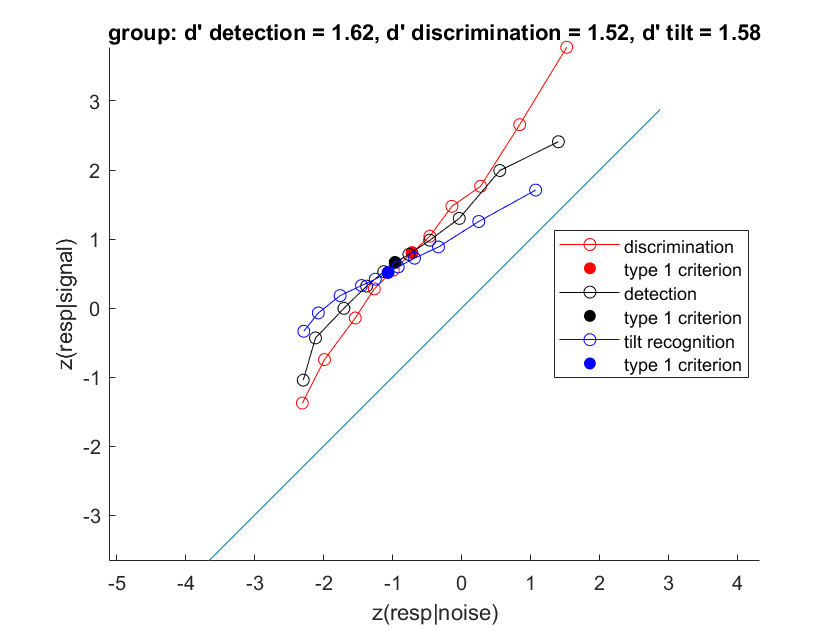

zDisS1G = []; %z stands for the inverse of the cumulative normal distribution
zDisS2G = [];
zDetSignalG = [];
zDetNoiseG = [];
zTiltTG = [];
zTiltVG = [];

DetSlopes = nan(N,1);
DisSlopes = nan(N,1);
TiltSlopes = nan(N,1);

DetR2 = nan(N,1);
DisR2 = nan(N,1);
TiltR2 = nan(N,1);

for s=1:35
        
    %create response count vectors, compute response probabilities 
    % and extract corresponding Z values
    DetSignalResponseCount = nR_signal(s,:);
    pDetSignal = DetSignalResponseCount/sum(DetSignalResponseCount);
    zDetSignal = norminv(cumsum(pDetSignal(end:-1:2)));
    
    DetNoiseResponseCount = nR_noise(s,:);
    pDetNoise = DetNoiseResponseCount/sum(DetNoiseResponseCount);
    zDetNoise = norminv(cumsum(pDetNoise(end:-1:2)));
    
    DisS1ResponseCount = nR_S1(s,:);
    pDisS1 = DisS1ResponseCount/sum(DisS1ResponseCount);
    zDisS1 = norminv(cumsum(pDisS1(end:-1:2)));
    
    DisS2ResponseCount = nR_S2(s,:);
    pDisS2 = DisS2ResponseCount/sum(DisS2ResponseCount);
    zDisS2 = norminv(cumsum(pDisS2(end:-1:2)));
    
    TiltTResponseCount = nR_tilted(s,:);
    pTiltT = TiltTResponseCount/sum(TiltTResponseCount);
    zTiltT = norminv(cumsum(pTiltT(end:-1:2)));
    
    TiltVResponseCount = nR_vertical(s,:);
    pTiltV = TiltVResponseCount/sum(TiltVResponseCount);
    zTiltV = norminv(cumsum(pTiltV(end:-1:2)));
    
    %plot
%     figure;
%     hold on;
%     axis equal
%     plot(zDisS1,zDisS2,'-or')
%     scatter(zDisS1(6), zDisS2(6), 'red','filled')
%     plot(zDetNoise, zDetSignal, '-ok')
%     scatter(zDetNoise(6), zDetSignal(6),'black','filled')
%     plot(zTiltV, zTiltT, '-ob')
%     scatter(zTiltV(6), zTiltT(6),'blue','filled')
%     refline(1,0)    
%     xlabel('z(resp|noise)');
%     ylabel('z(resp|signal)');
%     title(sprintf('%d: d detection = %.2f, d discrimination = %.2f, d tilt = %.2f', ...
%        s, zDetSignal(6)-zDetNoise(6), zDisS2(6)-zDisS1(6),zTiltT(6)-zTiltV(6)));
%     if s==1
%         legend('discrimination','type 1 criterion', 'detection', 'type 1 criterion','Location','best')
%     end
%     
    zDisS1G = [zDisS1G; zDisS1];
    zDisS2G = [zDisS2G; zDisS2];
    zDetSignalG = [zDetSignalG; zDetSignal];
    zDetNoiseG = [zDetNoiseG; zDetNoise];
    zTiltTG = [zTiltTG; zTiltT];
    zTiltVG = [zTiltVG; zTiltV];
    
    % sometimes, due to a floating point error, the sum of all
    % probabilities is a bit lower than 1, and then the inverse normal
    % cumulative of this number is not inf, but a number like 8.
    % Theoretically, the highest number that is not infinity that we should
    % expect is abs(norminv(1/(25*5))=2.4089. So we ignore all numbers
    % higher than 3 in absolute value, as they refelct a floating point
    % error.
    
    robustDetBins = find(abs(zDetNoise)<3 & abs(zDetSignal)<3);
    [DetCoefs1,DetS1] = polyfit(zDetNoise(robustDetBins),zDetSignal(robustDetBins),1);
    [DetCoefs2,DetS2] = polyfit(zDetSignal(robustDetBins),zDetNoise(robustDetBins),1);

    DetSlopes(s) = mean([DetCoefs1(1),1/DetCoefs2(1)]);
    %from here: https://uk.mathworks.com/matlabcentral/answers/159369-polyfit-and-r-2-value
    DetR2(s) = 1 - (DetS1.normr/norm(zDetSignal(robustDetBins) - mean(zDetSignal(robustDetBins))))^2;

    robustDisBins = find(abs(zDisS1)<3 & abs(zDisS2)<3);
    [DisCoefs1,DisS1] = polyfit(zDisS1(robustDisBins),zDisS2(robustDisBins),1);
    [DisCoefs2,DisS2] = polyfit(zDisS2(robustDisBins),zDisS1(robustDisBins),1);
    
    DisSlopes(s) = mean([DisCoefs1(1),1/DisCoefs2(1)]);
    
    %from here: https://uk.mathworks.com/matlabcentral/answers/159369-polyfit-and-r-2-value
    DisR2(s) = 1 - (DisS1.normr/norm(zDisS1(robustDisBins) - mean(zDisS2(robustDisBins))))^2;
    
    robustTiltBins = find(abs(zTiltT)<3 &abs(zTiltV)<3);
    [TiltCoefs1,TiltS1] = polyfit(zTiltV(robustTiltBins),zTiltT(robustTiltBins),1);
    [TiltCoefs2,TiltS2] = polyfit(zTiltT(robustTiltBins),zTiltV(robustTiltBins),1);
    TiltSlopes(s) = mean([TiltCoefs1(1),1/TiltCoefs2(1)]);
    %from here: https://uk.mathworks.com/matlabcentral/answers/159369-polyfit-and-r-2-value
    TiltR2(s) = 1 - (TiltS1.normr/norm(zTiltV(robustTiltBins) - mean(zTiltT(robustTiltBins))))^2;
end

% [h,sig,ci,stats]=ttest(log2(DisSlopes))
% [h,sig,ci,stats]=ttest(log2(DetSlopes))
% [h,sig,ci,stats]=ttest(log2(TiltSlopes))


zDisS1G(~isfinite(zDisS1G)) = 2.5*sign(zDisS1G(~isfinite(zDisS1G)));
zDisS2G(~isfinite(zDisS2G)) = 2.5*sign(zDisS2G(~isfinite(zDisS2G)));

zDetSignalG(~isfinite(zDetSignalG)) = 2.5*sign(zDetSignalG(~isfinite(zDetSignalG)));
zDetNoiseG(~isfinite(zDetNoiseG)) = 2.5*sign(zDetNoiseG(~isfinite(zDetNoiseG)));

zTiltTG(~isfinite(zTiltTG)) = 2.5*sign(zTiltTG(~isfinite(zTiltTG)));
zTiltVG(~isfinite(zTiltVG)) = 2.5*sign(zTiltVG(~isfinite(zTiltVG)));
%plot
    figure;
    hold on;
    axis equal
    plot(nanmean(zDisS1G),nanmean(zDisS2G),'-or')
    scatter(nanmean(zDisS1G(:,6)), nanmean(zDisS2G(:,6)), 'red','filled')
    plot(nanmean(zDetNoiseG), nanmean(zDetSignalG), '-ok')
    scatter(nanmean(zDetNoiseG(:,6)), nanmean(zDetSignalG(:,6)),'black','filled')
    plot(nanmean(zTiltVG), nanmean(zTiltTG), '-ob')
    scatter(nanmean(zTiltVG(:,6)), nanmean(zTiltTG(:,6)),'blue','filled')
    refline(1,0)    
    xlabel('z(resp|noise)');
    ylabel('z(resp|signal)');
    title(sprintf('group: d'' detection = %.2f, d'' discrimination = %.2f, d'' tilt = %.2f', ...
       nanmean(zDetSignalG(:,6))-nanmean(zDetNoiseG(:,6)), nanmean(zDisS2G(:,6))-nanmean(zDisS1G(:,6)),...
       nanmean(zTiltTG(:,6))-nanmean(zTiltVG(:,6))));
        legend('discrimination','type 1 criterion', 'detection', 'type 1 criterion','tilt recognition', 'type 1 criterion','Location','best')

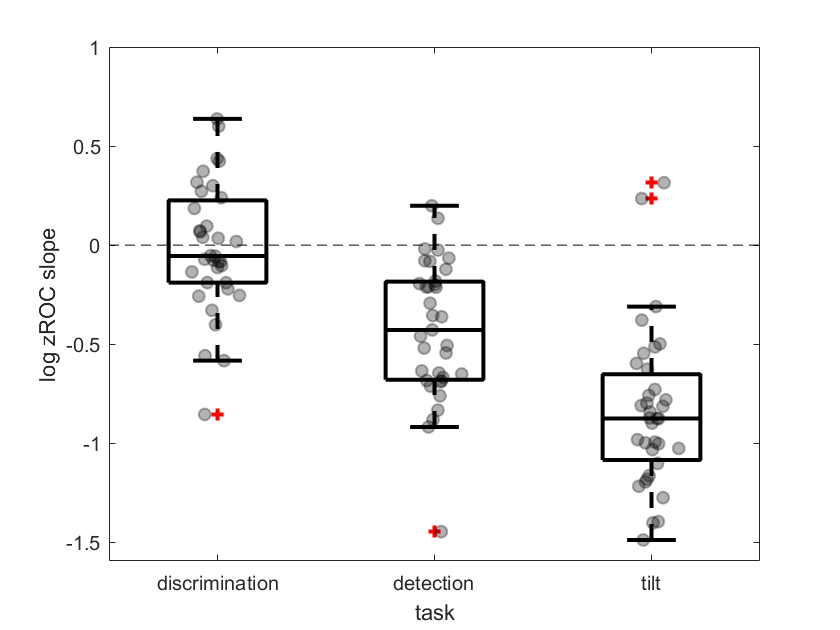


save(fullfile('..','analyzed','slopes.mat'),'DisSlopes','DetSlopes','TiltSlopes')

noise1 = normrnd(0,0.05,1,N);
noise2 = normrnd(0,0.05,1,N);
noise3 = normrnd(0,0.05,1,N);

figure; hold on;
h=boxplot([log2(DisSlopes) log2(DetSlopes) log2(TiltSlopes)],'Colors','k');
set(h,{'linew'},{2})
% plot([ones(1,35)+noise1; 2*ones(1,35)+noise2],[meanAccDis;meanAccDet],'color',[0.5,0.5,0.5]);
scatter(ones(N,1)+noise1',log2(DisSlopes),'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1, 'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(2*ones(N,1)+noise2',log2(DetSlopes),'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
scatter(3*ones(N,1)+noise2',log2(TiltSlopes),[],'MarkerEdgeColor','k','MarkerFaceColor',...
    [0,0,0],'LineWidth',1,'MarkerEdgeAlpha',0.3,'MarkerFaceAlpha',0.3);
ylabel('log zROC slope');

xlim([0.5,3.5]); xlabel('task');
% ylim([0.4,1]);
plot([0.5,3.5],[0,0],'k--')
set(gca,'xtick',[1:3],'xticklabel',{'discrimination','detection','tilt'})
fig = gcf;
s=hgexport('readstyle','presentation');
s.Format = 'png';
s.Width = 12;
s.Height = 10;
hgexport(fig,'figures/slope_ratio',s);

## 5. RT analysis

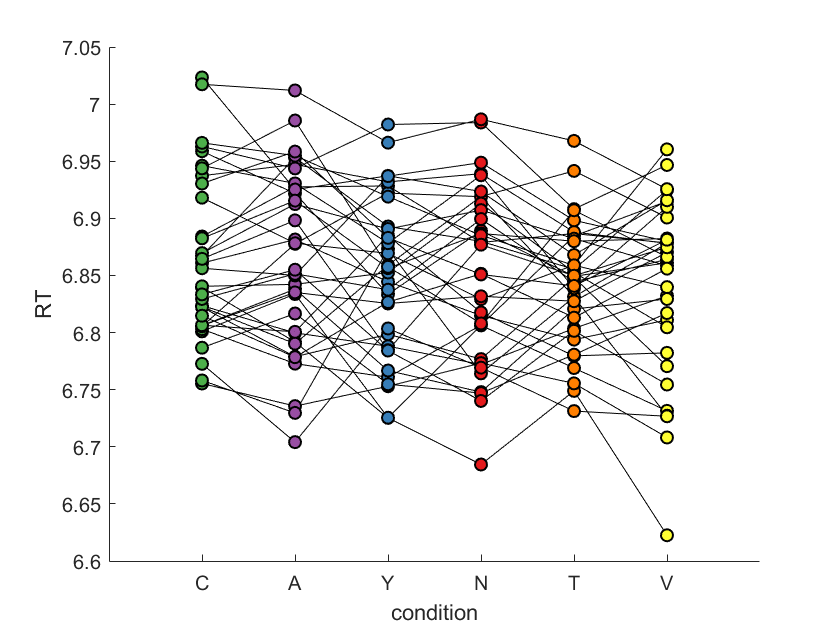

RT_A = [];
RT_Y = [];
RT_N = [];
RT_V = [];
RT_T = [];

for s = 1:length(subjects)
    
    subject = data_struct(subjects{s});
    
        RT_C(s) = nanmean(log(subject.DisRT(subject.DisResp==1 & subject.DisInclude==1)*1000));
        RT_A(s) = nanmean(log(subject.DisRT(subject.DisResp==0 & subject.DisInclude==1)*1000));
        RT_Y(s) = nanmean(log(subject.DetRT(subject.DetResp==1 & subject.DetInclude==1)*1000));
        RT_N(s) = nanmean(log(subject.DetRT(subject.DetResp==0 & subject.DetInclude==1)*1000));
        RT_T(s) = nanmean(log(subject.TiltRT(subject.TiltResp==1 & subject.TiltInclude==1)*1000));
        RT_V(s) = nanmean(log(subject.TiltRT(subject.TiltResp==0 & subject.TiltInclude==1)*1000));
        
end

figure; hold on;
plot([RT_C;RT_A;RT_Y;RT_N; RT_T; RT_V],'k');
scatter(ones(N,1),RT_C,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(2*ones(N,1),RT_A,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(4,:),'LineWidth',1);
scatter(3*ones(N,1),RT_Y,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(N,1),RT_N,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(5*ones(N,1),RT_T,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(6,:),'LineWidth',1);
scatter(6*ones(N,1),RT_V,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(7,:),'LineWidth',1);
ylabel('RT');
xlim([0,7]); xlabel('condition');
set(gca,'xtick',[1:6],'xticklabel',{'C','A','Y','N','T','V'})